# Home Assignment 1

Name and surname: **Jakob [dopolni priimek]**

I declare that the work presented below is entirely my own and has been produced independently (enter YES or NO and add a comment if necessary): YES

I declare that I have accurately and correctly cited all content created using artificial intelligence tools (enter YES or NO and add a comment if necessary): **YES.**

List of artificial intelligence tools used, if any (in addition to the name of each tool, also specify the subscription plan or version): Chat GPT. Pomoč pri razlai navodil, pripravi grafov za poročilo.

## Initial robot configurations

% Each configuration is given as [x; y; phi; gamma] (x and y are in meters, and phi and gamma are in radians)
qA = [0.3; 0.9; 0; 0];
qB = [0.9; 0.9; 0; 0];
qC = [0.4; 0.9; pi; 0];
qD = [0.8; 0.7; pi/2; 0];
qS = [0.6; 0.9; 0; 0];

noise = 1; % 1 - enable noise, 0 - disable noise
anima = 0; % 0 - no animation, 1 - animation, >1 - animation with decimation

## Exercise 1: Single robot

Metoda: skupno vodenje do vmesnih leg, brez vej glede na goalId. Datoteki controlParking.m in controlParkingLim.m hranita samo stanje; regulator je v parkingControl.m, izbor vmesnih leg pa v parkingPlan.m.

Iz podane kinematike velja v = vs*cos(gamma), omega = vs*sin(gamma)/D in gamma_dot = ws - omega. Zato iz zelene ukrivljenosti k dobimo gamma_ref = atan(D*k). Notranja zanka uporablja ws = vs*sin(gamma)/D + 10*wrapToPi(gamma_ref-gamma). S tem upostevamo razliko med kotno hitrostjo vozila in prednjega dela.

Sledimo premicam in kroznim lokom s predkrmiljenjem ukrivljenosti ter povratno vezavo precne in kotne napake. Na prehodu se ustavimo in nastavimo krmilni kot, da ne rezemo ovinkov. Blizu cilja uporabimo proporcionalno vodenje vzdolzne napake ter umirimo hitrost. Obe razlicici imata isti referencni polmer (zasuk 28.5 stopinje); neomejeni krmilnik dopusca vecje povratne popravke. Brez omejitve zasuka lahko zadnji majhen popravek smeri opravimo na mestu.

Podlaga: 3_AMS_Control.pdf, prosojnice 10-11, 15-17 in 23. Za samodejen izbor vmesnih leg je dodan hibridni A* (4_AMS_PathPlanning.pdf, prosojnica 45, in 4a_AMS_Planiranje_poti_v_grafu.pdf). To je dodatek k vodenju; Hevristiko za obvoz ovir dobimo z 2D postopkom Dijkstra. izbrana pot ni dokazano najkrajsa. Iskanje zacnemo v cilju in pot obrnemo, da najprej resimo tesni del parkirnega manevra. Bliznji legi lahko povezemo tudi s tremi tangentnimi kroznicami in vzvratnim srednjim lokom; to omogoci obrat smeri brez velikega krozenja.

Meritve filtriramo z napovedjo iz kinematike in uporabljenih omejitev koles (T = 0.01 s, vmax = 0.3 m/s, amax = 1 m/s^2). Blizu cilja je filtriranje mocnejse. Stop zahtevamo sele po 25 zaporednih ustreznih ocenah, ob potrditvi inside. Navedene napake v tabelah so izracunane iz dejanske koncne lege simulatorja, ne iz filtrirane meritve.

Preizkuse izvajamo z runParkingCase.m: izvirni updateVehicle z ode45, VehicleConstraints in Map ostanejo nespremenjeni. Zaradi hitrosti ne posodabljamo grafike pri vsakem vzorcu. Preseke pravokotnikov preverjamo s projekcijami na njihove osi (SAT); koncno lego preveri tudi Map. parkingResults.m izrise rezultate, store.m jih shrani v MAT-datoteke. Vsi spodnji primeri imajo vkljucen merilni sum in navedeno seme rng.

### Case 1: From the known initial configuration A to P11

rng(101);
data = runParkingCase(qA, 11, false, noise);

P11: t=19.85 s, ed=0.499 mm, ephi=0.043 deg, trki=0


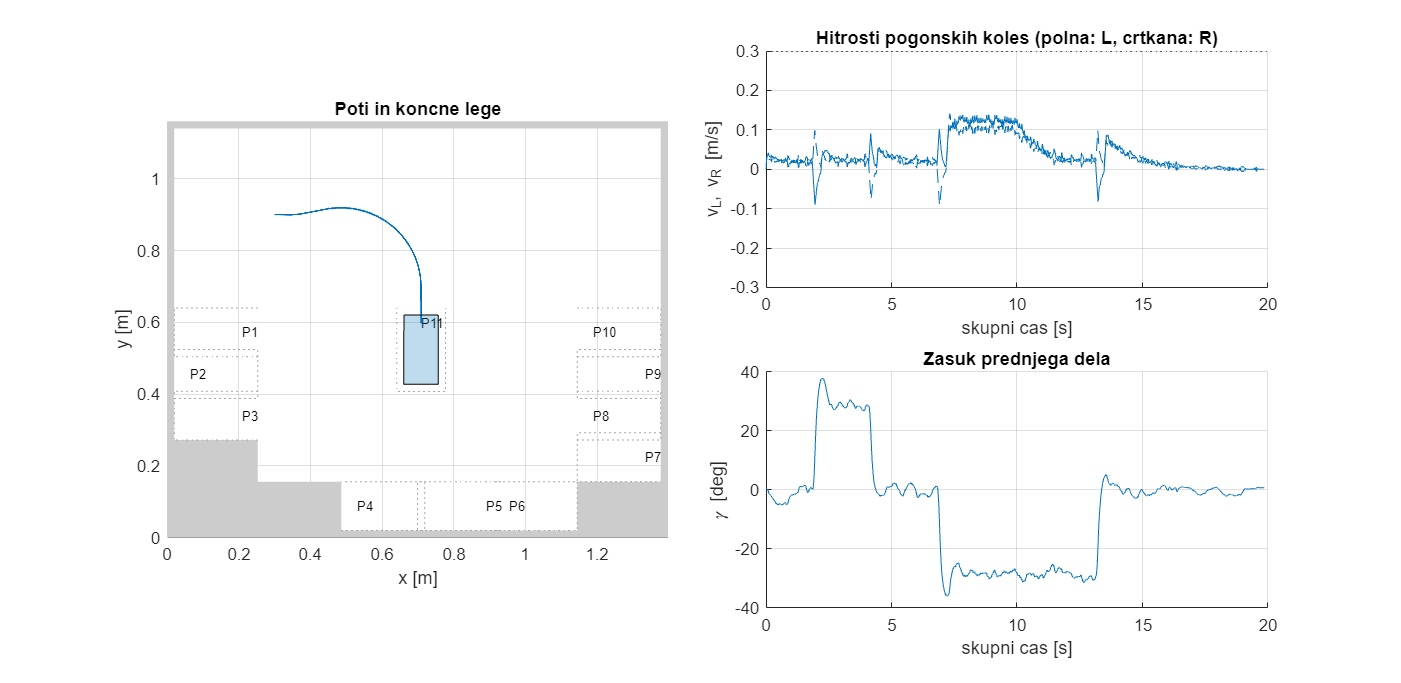

ans = 1x9 table
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    ________    ________    _________    ____

      1       11     19.85    0.63667    0.49914    0.043014    0.14171         1         0  


store('ex1case1', data);
parkingResults(data, false)

### Case 2: From the known initial configuration B to P11

rng(102);
data = runParkingCase(qB, 11, false, noise);

P11: t=27.33 s, ed=0.636 mm, ephi=0.084 deg, trki=0


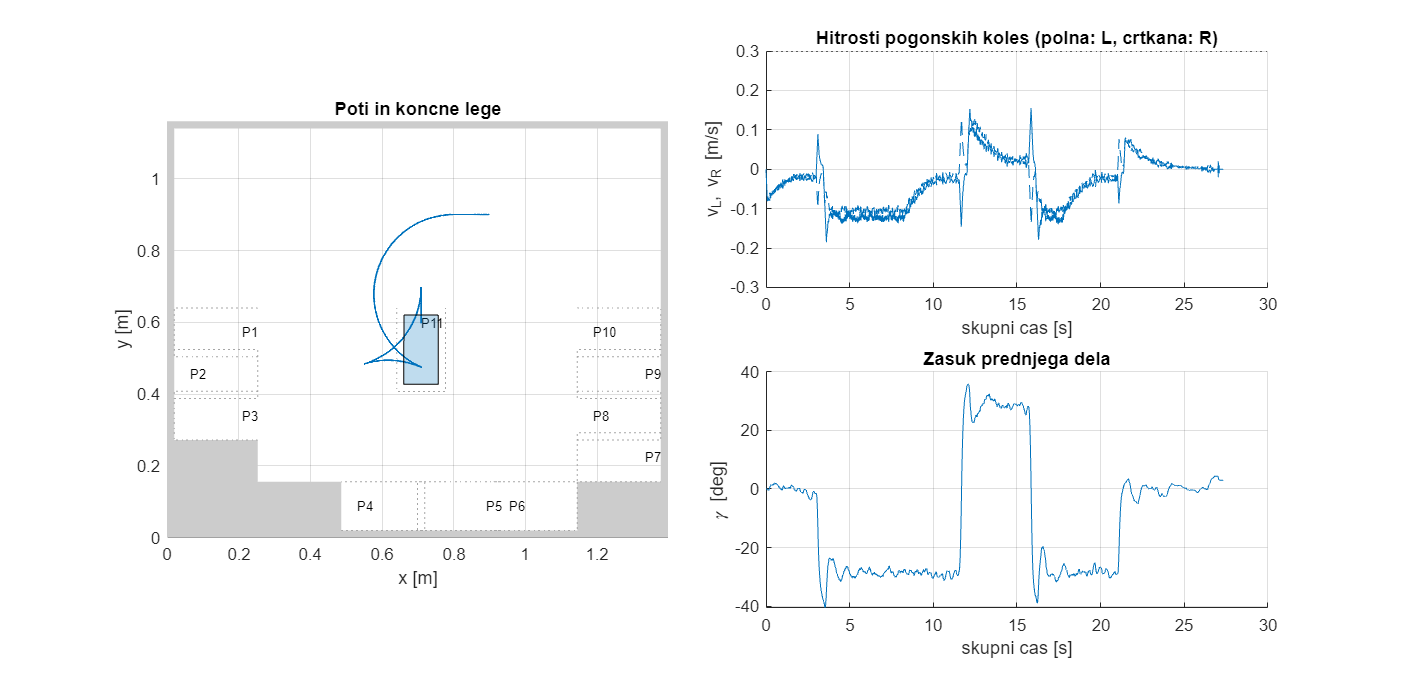

ans = 1x9 table
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1       11     27.33    1.2542    0.63603    0.083756    0.18534         1         0  


store('ex1case2', data);
parkingResults(data, false)

### Case 3: From the known initial configuration C to P11

rng(103);
data = runParkingCase(qC, 11, false, noise);

P11: t=27.59 s, ed=0.613 mm, ephi=0.073 deg, trki=0


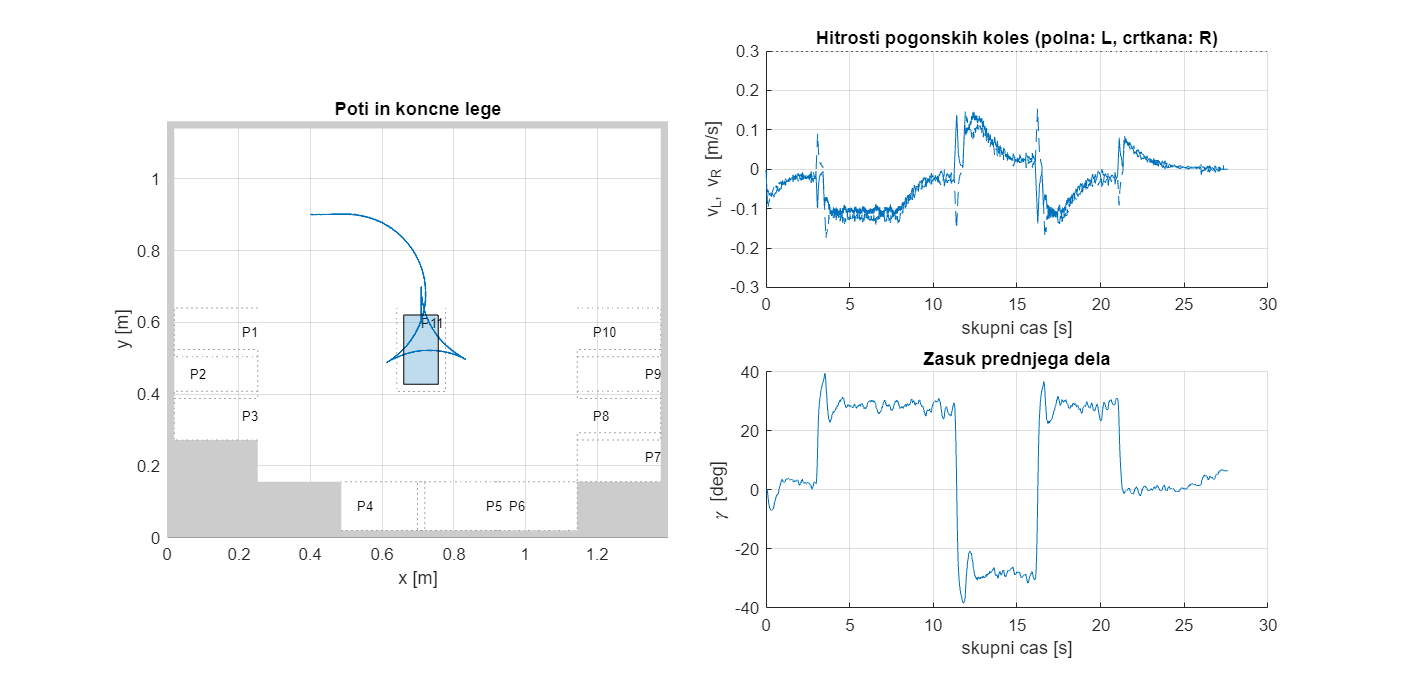

ans = 1x9 table
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1       11     27.59    1.2543    0.61319    0.072887    0.17484         1         0  


store('ex1case3', data);
parkingResults(data, false)

### Case 4: From the known initial configuration D to P11

rng(104);
data = runParkingCase(qD, 11, false, noise);

P11: t=24.72 s, ed=0.469 mm, ephi=0.027 deg, trki=0


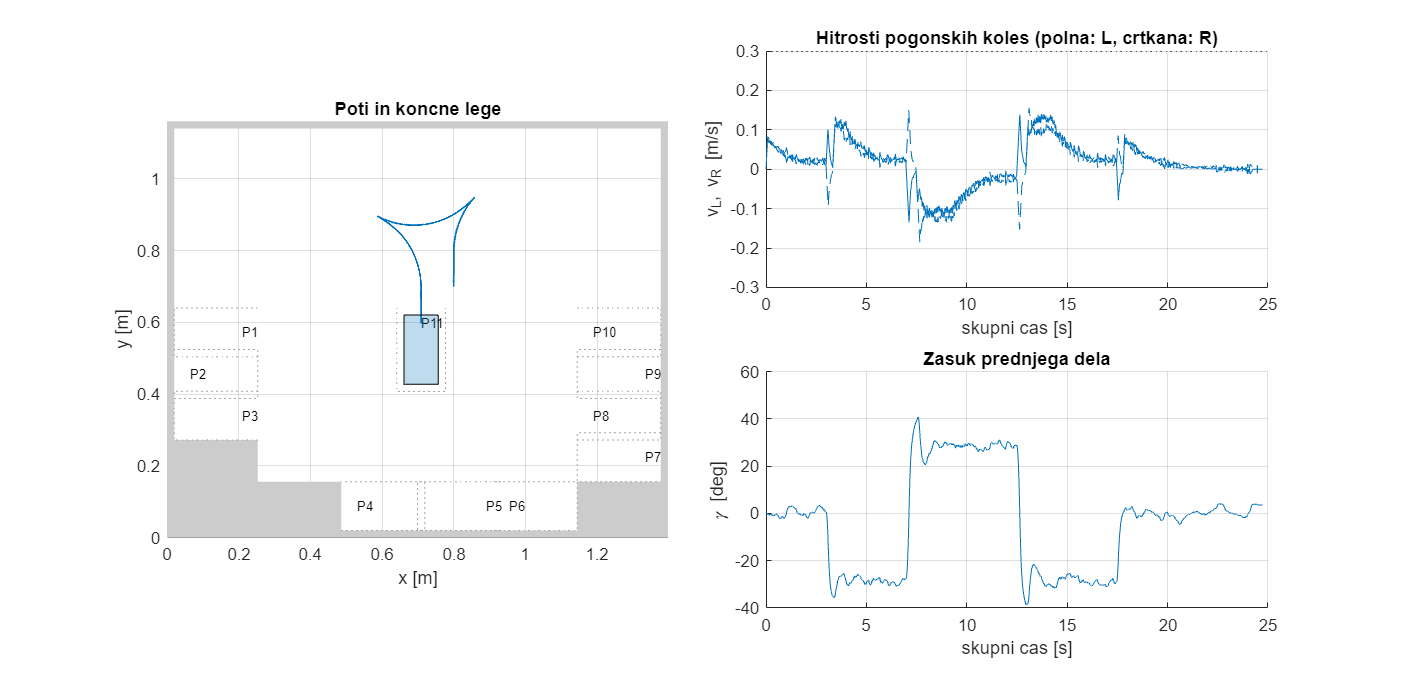

ans = 1x9 table
    robot    cilj    cas_s     pot_m     ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    ______    ________    ________    _________    ____

      1       11     24.72    0.90225    0.4694    0.02727     0.18548         1         0  


store('ex1case4', data);
parkingResults(data, false)

### Case 5: From the known initial configuration A to P1

rng(105);
data = runParkingCase(qA, 1, false, noise);

P01: t=20.61 s, ed=0.631 mm, ephi=0.148 deg, trki=0


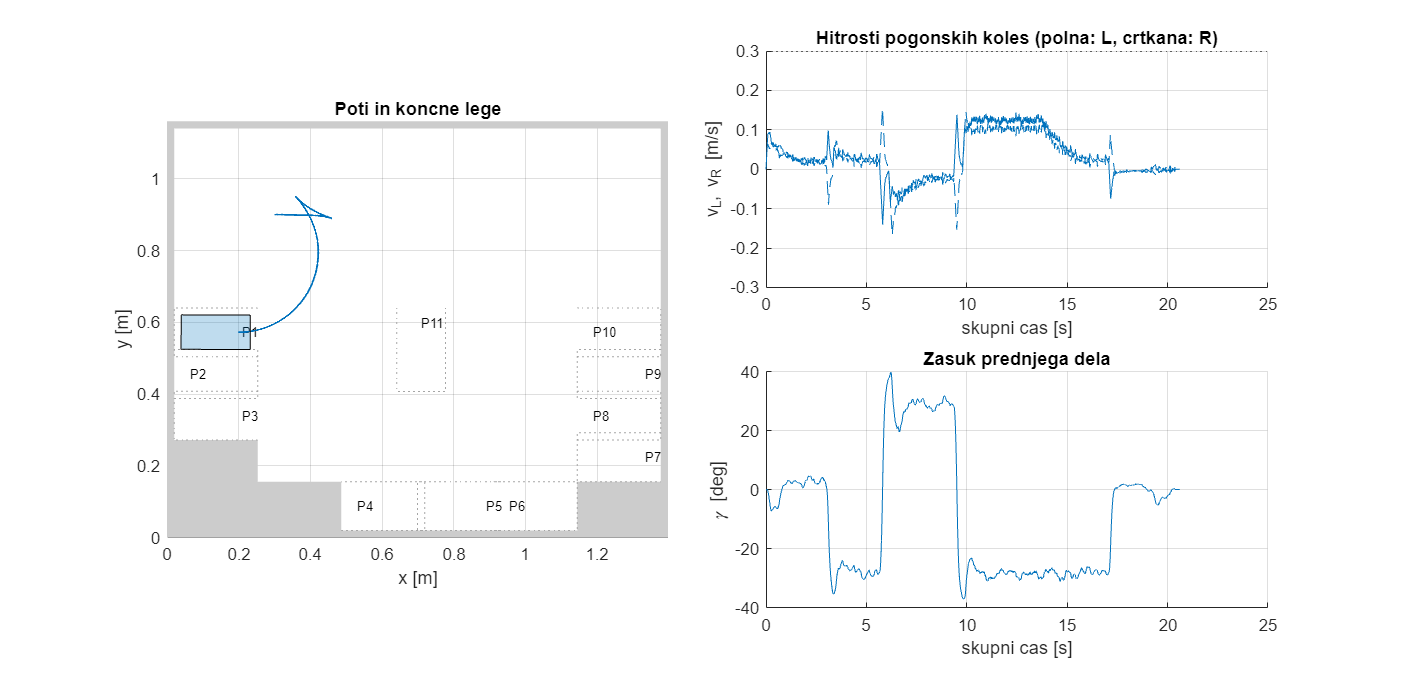

ans = 1x9 table
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    ________    ________    _________    ____

      1       1      20.61    0.81513    0.63088    0.14846     0.16748         1         0  


store('ex1case5', data);
parkingResults(data, false)

### Case 6: From the known initial configuration A to P7

rng(106);
data = runParkingCase(qA, 7, false, noise);

P07: t=40.61 s, ed=0.499 mm, ephi=0.022 deg, trki=0


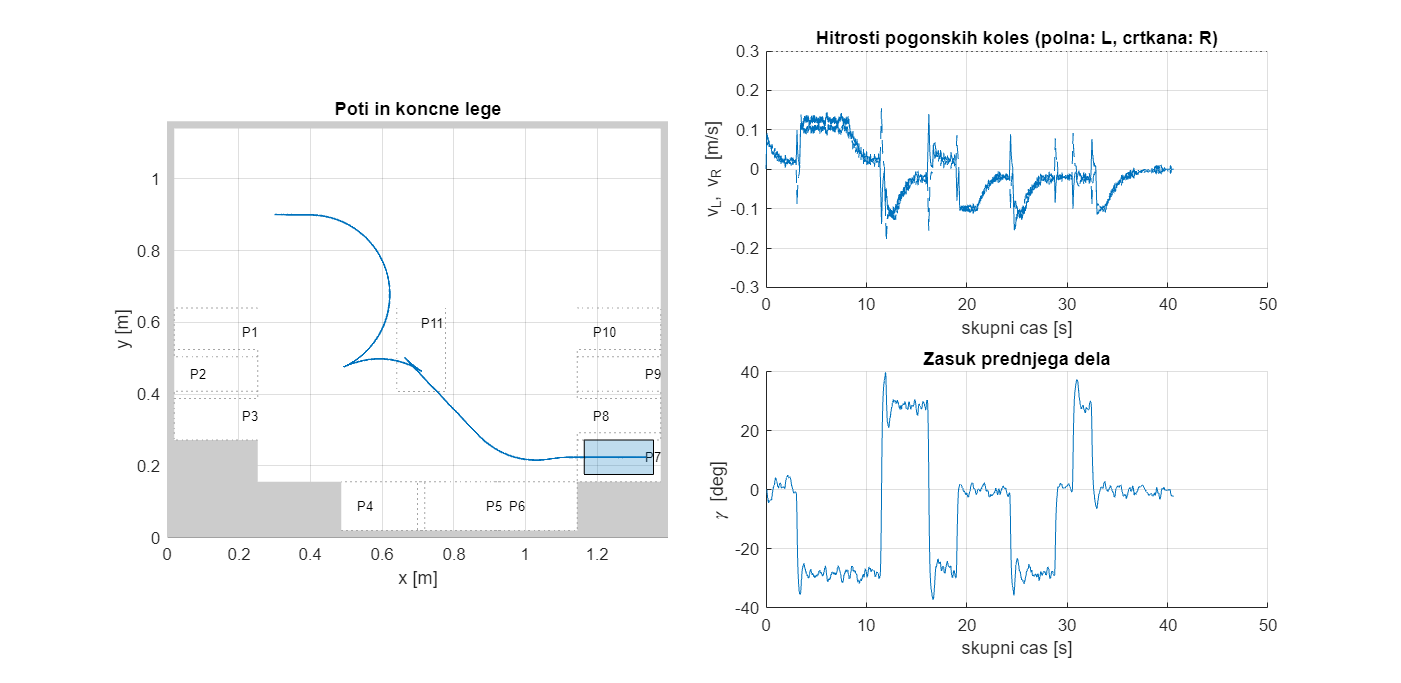

ans = 1x9 table
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1       7      40.61    1.7678    0.49928    0.022402     0.1848         1         0  


store('ex1case6', data);
parkingResults(data, false)

### Case 7: From the known initial configuration A to P5

rng(107);
data = runParkingCase(qA, 5, false, noise);

P05: t=43.86 s, ed=0.626 mm, ephi=0.027 deg, trki=0


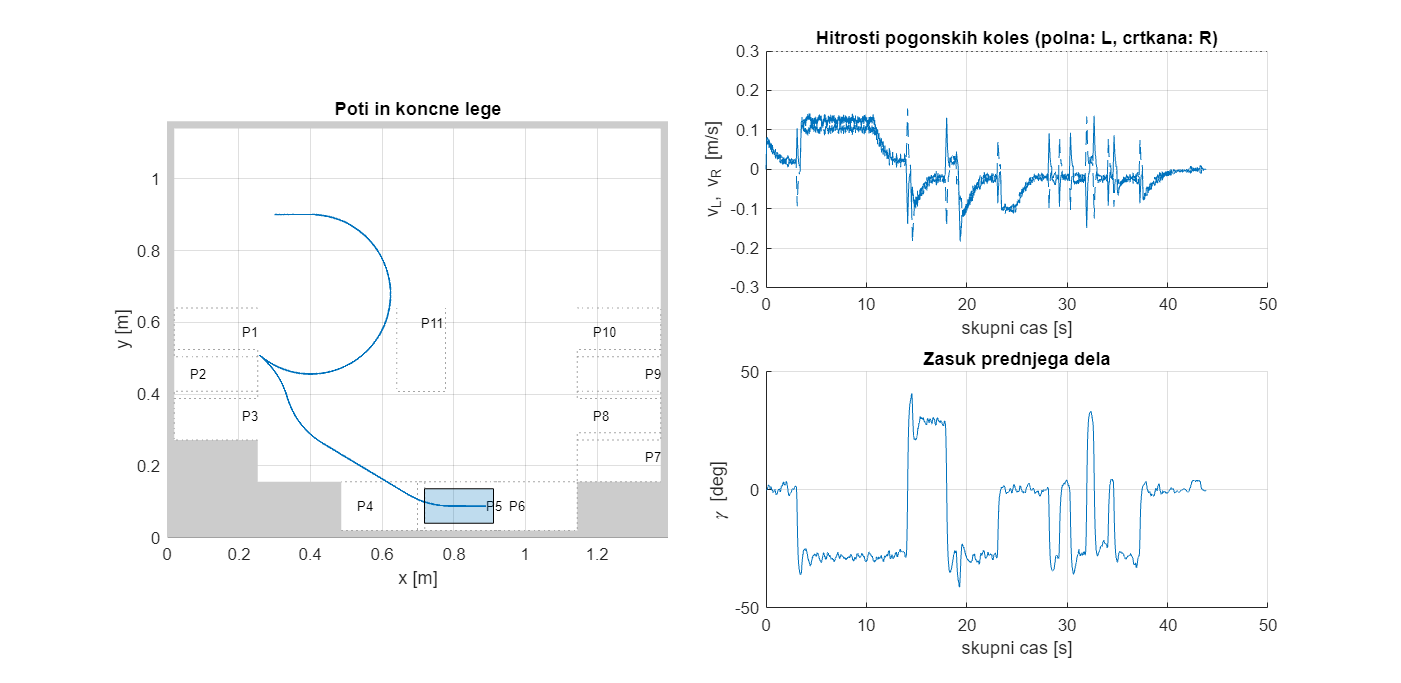

ans = 1x9 table
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1       5      43.86    1.7999    0.62622    0.027379     0.1858         1         0  


store('ex1case7', data);
parkingResults(data, false)

### Case 8: From a random initial configuration to a random parking spot

rng(401);
data = runParkingCase([], 0, false, noise);

P11: t=22.31 s, ed=0.732 mm, ephi=0.216 deg, trki=0


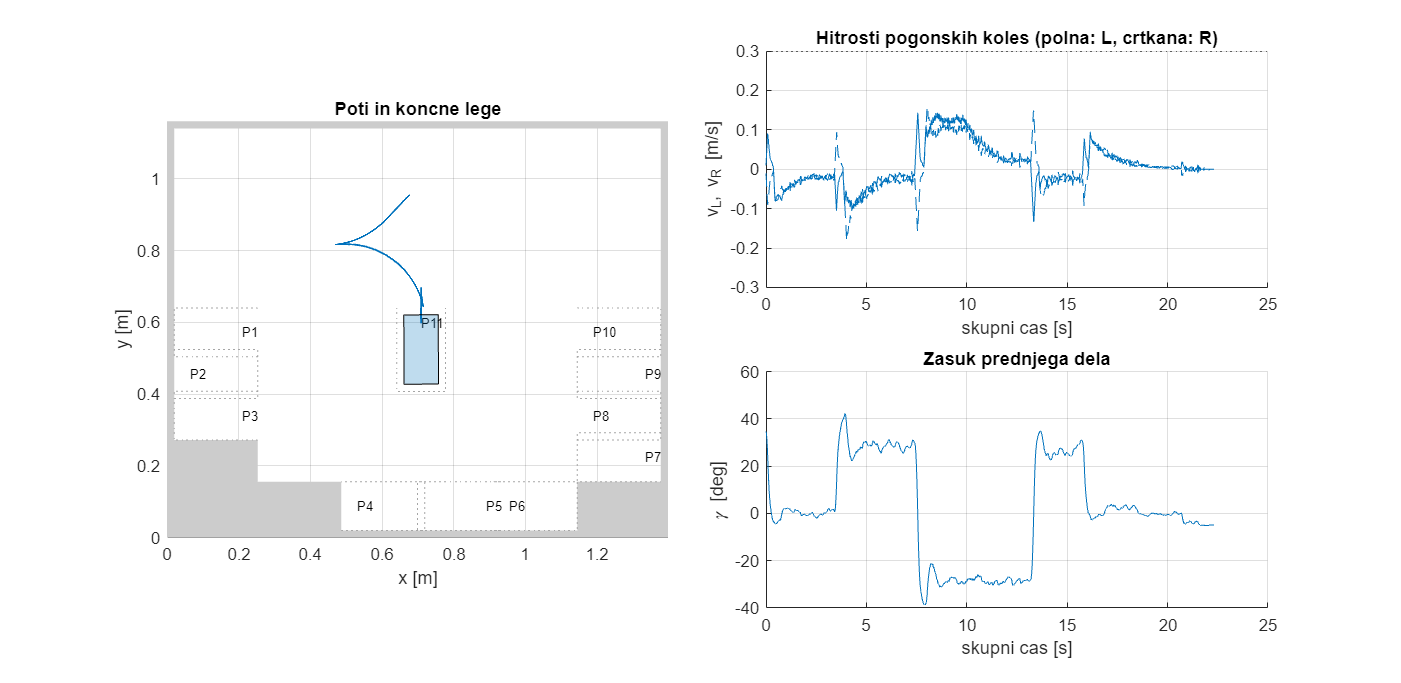

ans = 1x9 table
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    ________    ________    _________    ____

      1       11     22.31    0.73468    0.73198     0.2164      0.1822         1         0  


store('ex1random1', data);
parkingResults(data, false)

## Exercise 2: Multiple robots

Regulator je isti kot pri prvi nalogi. Ob prihodu novega robota se persistent stanje ponastavi. Ze parkirana vozila se prevzamejo iz map.vehicleObstacles; pri izbiri odsekov preverimo celoten pravokotni obris vozila. Stevilka vozila in parkirisca ne dolocata posebnega manevra. V prostem prostoru uporabimo do 6 mm rezerve, blizu zacetne in ciljne lege se rezerva postopno zmanjsa.

### Case 1: From the same known initial configuration S to P1, P8, P10, P3 and P6

rng(201);
data = runParkingCase(qS, [1, 8, 10, 3, 6], false, noise);

P01: t=23.62 s, ed=0.590 mm, ephi=0.000 deg, trki=0
P08: t=43.10 s, ed=0.702 mm, ephi=0.022 deg, trki=0
P10: t=31.40 s, ed=0.448 mm, ephi=0.191 deg, trki=0
P03: t=33.57 s, ed=0.589 mm, ephi=0.185 deg, trki=0
P06: t=55.70 s, ed=0.633 mm, ephi=0.093 deg, trki=0


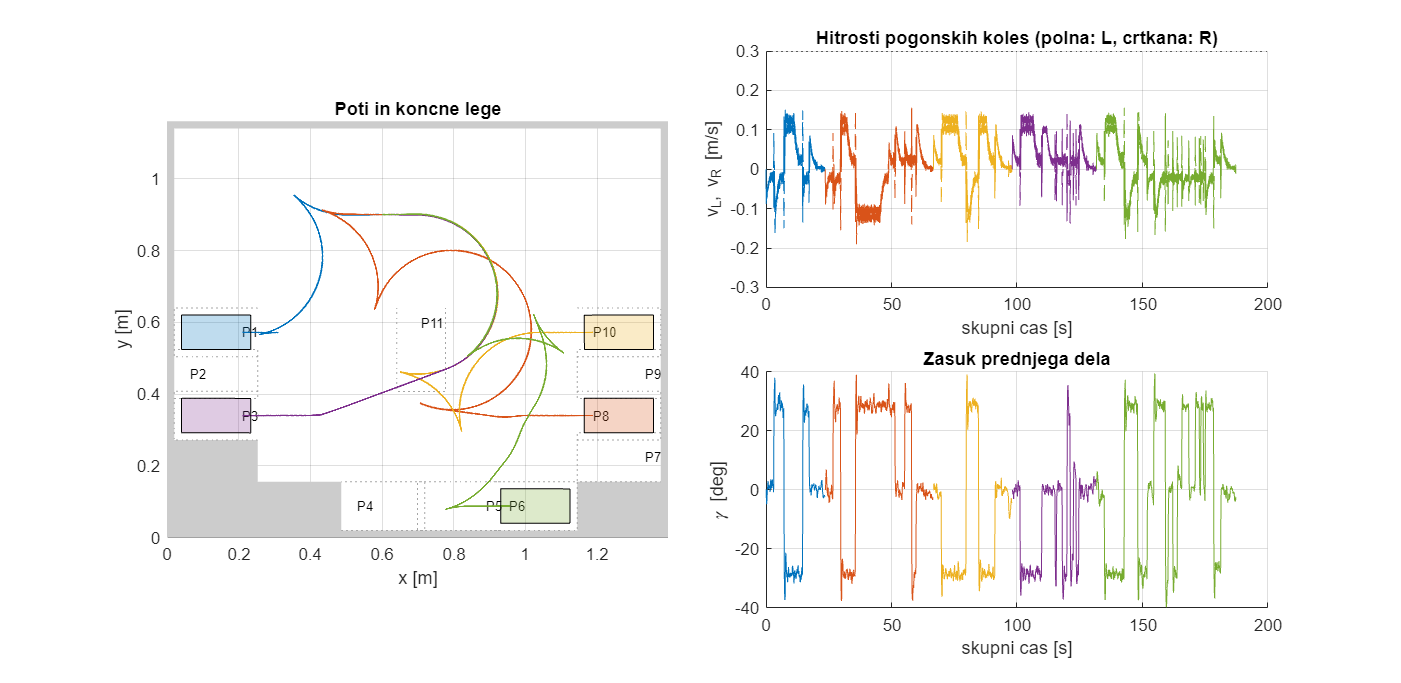

ans = 5x9 table
    robot    cilj    cas_s    pot_m      ed_mm      ephi_deg     vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    __________    ________    _________    ____

      1        1     23.62    0.9056    0.58966    8.2899e-05    0.16675         1         0  
      2        8      43.1    2.0727    0.70163      0.021813    0.19019         1         0  
      3       10      31.4    1.6526    0.44849       0.19052    0.18489         1         0  
      4        3     33.57    1.3431    0.58923       0.18528    0.14792         1         0  
      5        6      55.7    1.9058    0.63267      0.093026    0.17744         1         0  


store('ex2case1', data);
parkingResults(data, false)

### Case 2: From the same known initial configuration S to P2, P9, P7 and P4

rng(202);
data = runParkingCase(qS, [2, 9, 7, 4], false, noise);

P02: t=31.85 s, ed=0.559 mm, ephi=0.031 deg, trki=0
P09: t=34.40 s, ed=0.623 mm, ephi=0.046 deg, trki=0
P07: t=48.59 s, ed=0.613 mm, ephi=0.046 deg, trki=0
P04: t=44.74 s, ed=0.561 mm, ephi=0.383 deg, trki=0


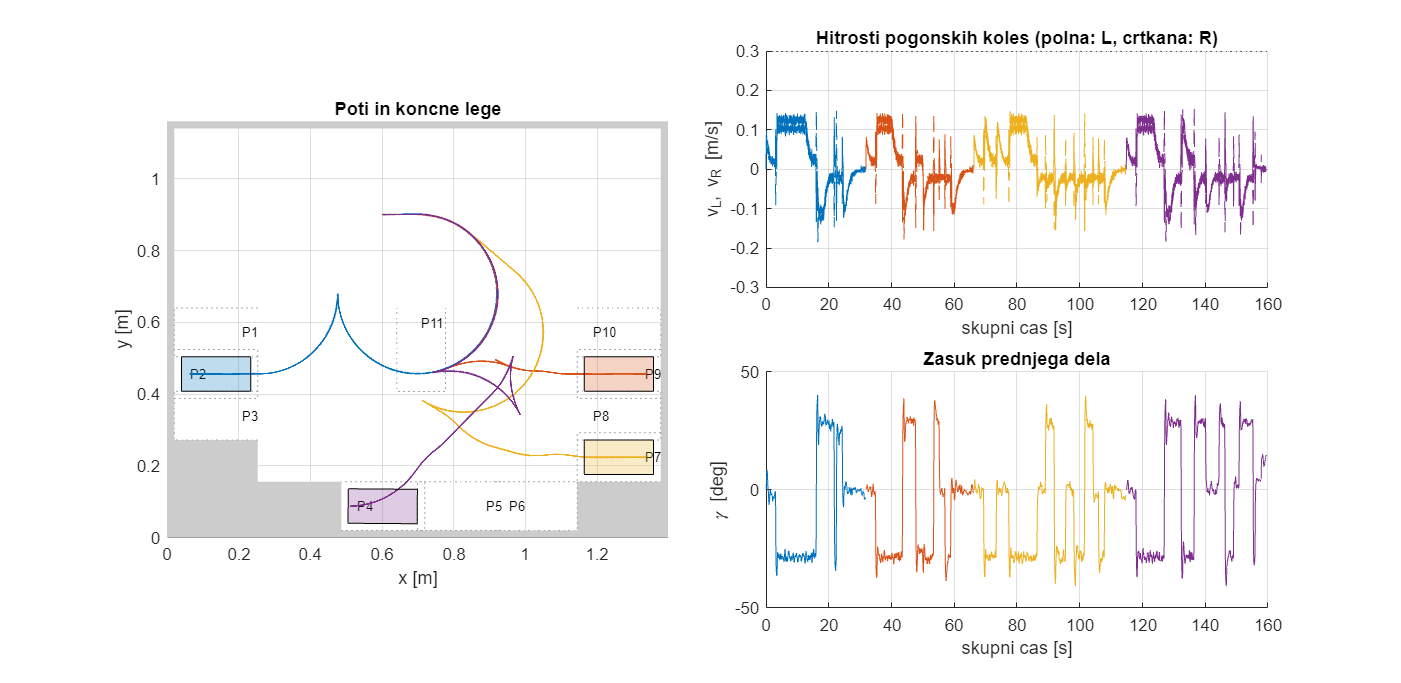

ans = 4x9 table
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1       2      31.85    1.6984    0.55923    0.031121    0.18527         1         0  
      2       9       34.4    1.3482    0.62277    0.046373    0.17813         1         0  
      3       7      48.59    1.7492    0.61261    0.045988    0.15691         1         0  
      4       4      44.74    1.8649    0.56113     0.38306    0.18319         1         0  


store('ex2case2', data);
parkingResults(data, false)

### Case 3: From the same known initial configuration S to P1, P3, P10, P8, P6, P2, P7, P9, P4 and P5

rng(203);
data = runParkingCase(qS, [1, 3, 10, 8, 6, 2, 7, 9, 4, 5], false, noise);

P01: t=24.01 s, ed=0.439 mm, ephi=0.011 deg, trki=0
P03: t=33.71 s, ed=0.551 mm, ephi=0.023 deg, trki=0
P10: t=32.07 s, ed=0.442 mm, ephi=0.068 deg, trki=0
P08: t=44.11 s, ed=0.628 mm, ephi=0.064 deg, trki=0
P06: t=50.10 s, ed=0.402 mm, ephi=0.086 deg, trki=0
P02: t=32.11 s, ed=0.602 mm, ephi=0.087 deg, trki=0
P07: t=48.22 s, ed=0.763 mm, ephi=0.078 deg, trki=0
P09: t=35.33 s, ed=0.575 mm, ephi=0.193 deg, trki=0
P04: t=50.95 s, ed=0.680 mm, ephi=0.412 deg, trki=0
P05: t=47.00 s, ed=0.595 mm, ephi=0.377 deg, trki=0


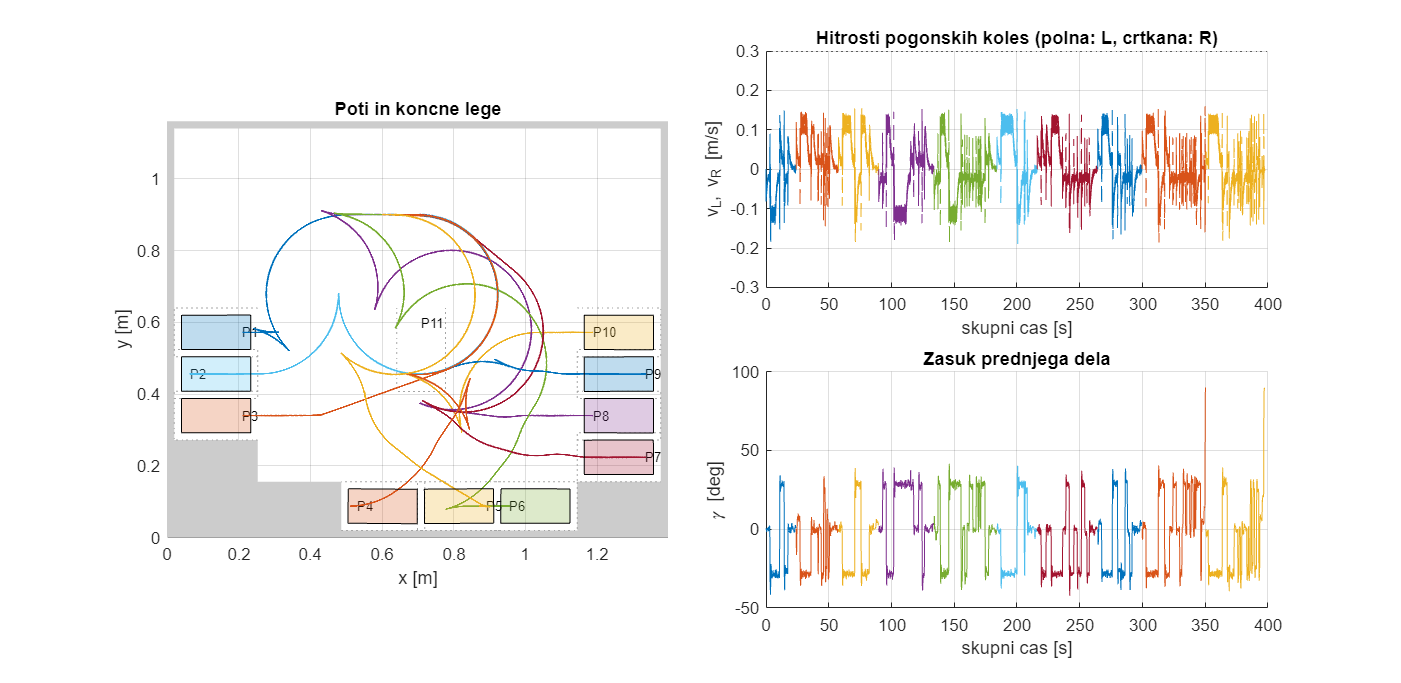

ans = 10x9 table
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    ________    ________    _________    ____

      1        1     24.01    0.90577    0.43941    0.010638    0.18433         1         0  
      2        3     33.71     1.3451    0.55106     0.02253    0.14587         1         0  
      3       10     32.07     1.6545    0.44175    0.067917    0.18462         1         0  
      4        8     44.11     2.0763    0.62778    0.063988    0.18475         1         0  
      5        6      50.1     1.8453    0.40163    0.085946       0.19         1         0  
      6        2  

store('ex2case3', data);
parkingResults(data, false)

### Case 4: From the same known initial configuration S to P11, P1, P2, P9, P10, P5, P3, P8, P7, P4 and P6

rng(204);
data = runParkingCase(qS, [11, 1, 2, 9, 10, 5, 3, 8, 7, 4, 6], false, noise);

P11: t=16.86 s, ed=0.727 mm, ephi=0.133 deg, trki=0
P01: t=23.41 s, ed=0.623 mm, ephi=0.159 deg, trki=0
P02: t=34.96 s, ed=0.542 mm, ephi=0.145 deg, trki=0
P09: t=32.13 s, ed=0.618 mm, ephi=0.102 deg, trki=0
P10: t=41.28 s, ed=0.524 mm, ephi=0.024 deg, trki=0
P05: t=39.18 s, ed=0.646 mm, ephi=0.005 deg, trki=0
P03: t=39.60 s, ed=0.627 mm, ephi=0.081 deg, trki=0
P08: t=40.91 s, ed=0.652 mm, ephi=0.046 deg, trki=0
P07: t=51.16 s, ed=0.572 mm, ephi=0.031 deg, trki=0
P04: t=63.63 s, ed=0.519 mm, ephi=0.053 deg, trki=0
P06: t=61.53 s, ed=0.628 mm, ephi=0.168 deg, trki=0


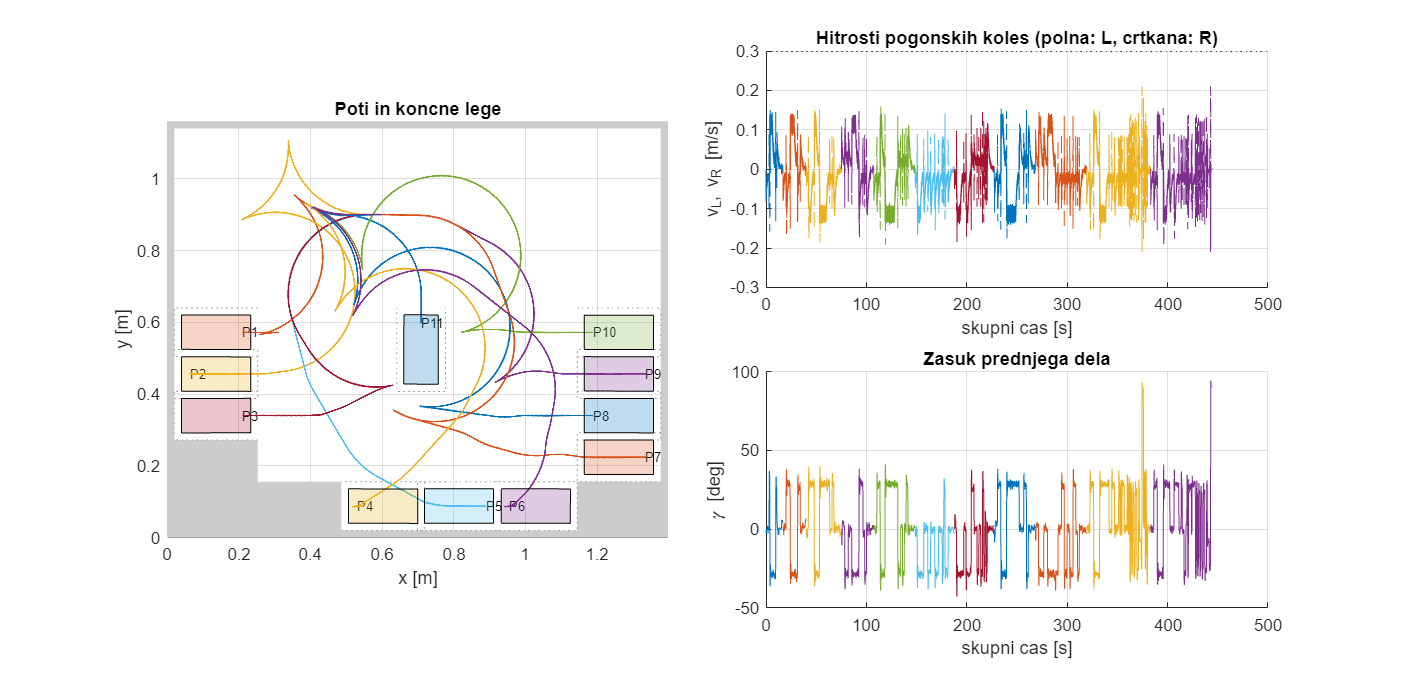

ans = 11x9 table
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg     vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    _________    ________    _________    ____

      1       11     16.86    0.55311    0.72672      0.13348    0.15803         1         0  
      2        1     23.41    0.90441    0.62316      0.15928    0.17371         1         0  
      3        2     34.96     1.6811    0.54162      0.14464    0.18489         1         0  
      4        9     32.13     1.2204    0.61779      0.10154    0.17643         1         0  
      5       10     41.28     1.8073    0.52413        0.024    0.19135         1         0  
      6    

store('ex2case4', data);
parkingResults(data, false)

### Case 5: From random initial configurations to random parking spots

rng(501);
data = runParkingCase([], zeros(1,11), false, noise);

P04: t=46.33 s, ed=0.738 mm, ephi=0.064 deg, trki=0
P03: t=21.67 s, ed=0.727 mm, ephi=0.169 deg, trki=0
P01: t=39.59 s, ed=0.678 mm, ephi=0.037 deg, trki=0
P11: t=19.50 s, ed=0.428 mm, ephi=0.039 deg, trki=0
P08: t=28.01 s, ed=0.592 mm, ephi=0.084 deg, trki=0
P07: t=47.15 s, ed=0.680 mm, ephi=0.007 deg, trki=0
P02: t=46.11 s, ed=0.633 mm, ephi=0.056 deg, trki=0
P06: t=46.10 s, ed=0.428 mm, ephi=0.162 deg, trki=0
P05: t=67.57 s, ed=0.706 mm, ephi=0.029 deg, trki=0
P10: t=46.84 s, ed=0.525 mm, ephi=0.192 deg, trki=0
P09: t=32.04 s, ed=0.577 mm, ephi=0.008 deg, trki=0


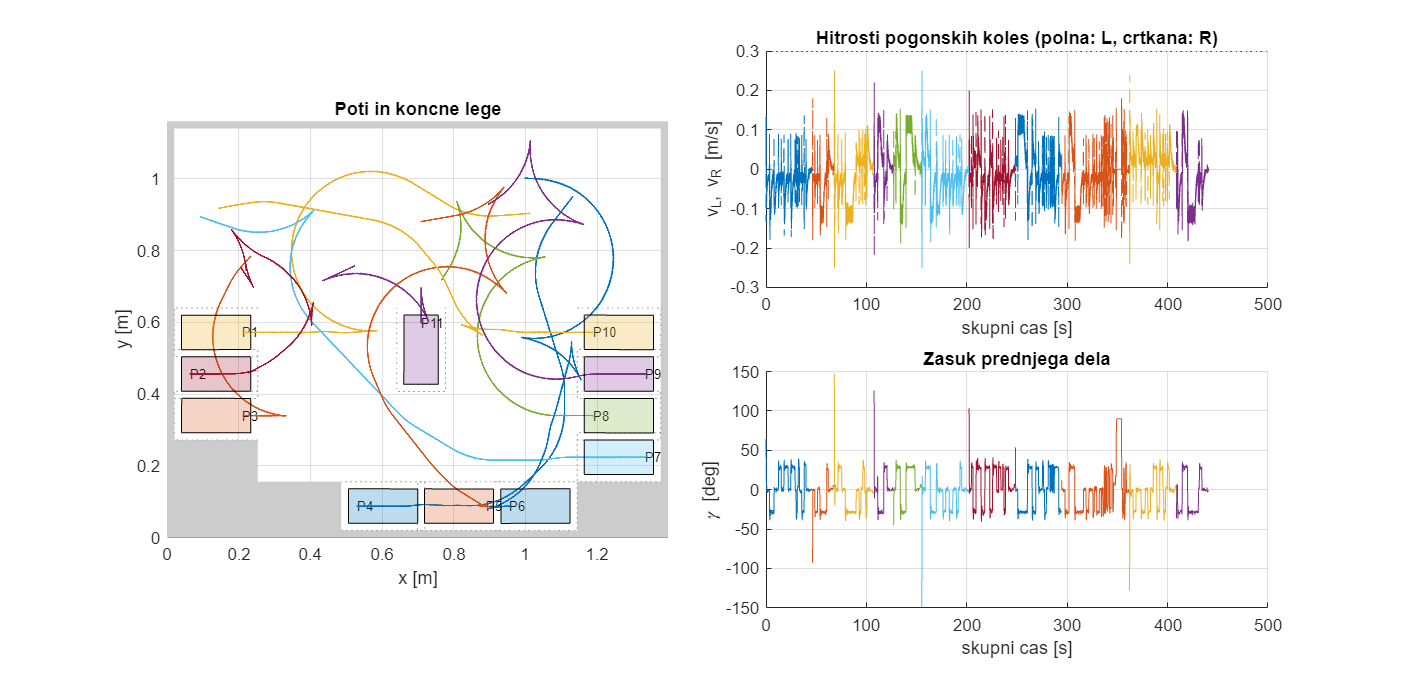

ans = 11x9 table
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg     vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    _________    ________    _________    ____

      1        4     46.33     1.3628    0.73751      0.06366    0.17888         1         0  
      2        3     21.67    0.70494    0.72683      0.16868    0.18021         1         0  
      3        1     39.59     1.5607    0.67766     0.037006       0.25         1         0  
      4       11      19.5    0.64726      0.428     0.039115       0.22         1         0  
      5        8     28.01     1.3166    0.59163     0.084036    0.18778         1         0  
      6    

store('ex2random1', data);
parkingResults(data, false)

## Exercise 3: Limited steering angle gamma

Klicemo isti regulator z gammaMax = pi/6. Vmesni loki imajo polmer D/tan(0.95*gammaMax), kar pusti nekaj rezerve za povratno vezavo. gamma_ref vedno omejimo na +/-30 stopinj. Obrat na mestu ni dovoljen; smer in lego dosezemo s premiki naprej in nazaj. Blizu cilja so premiki kratki do 5 mm, mreza za zdruzevanje leg pa gostejsa (2 mm za polozaj in 1 stopinja za orientacijo), da ostanejo dosegljivi tudi manevri med dvema parkiranima voziloma.

### Case 1: From the same known initial configuration S to P1, P8, P10, P3 and P6

rng(301);
data = runParkingCase(qS, [1, 8, 10, 3, 6], true, noise);

P01: t=23.13 s, ed=0.706 mm, ephi=0.037 deg, trki=0
P08: t=43.53 s, ed=0.505 mm, ephi=0.011 deg, trki=0
P10: t=31.51 s, ed=0.536 mm, ephi=0.019 deg, trki=0
P03: t=33.46 s, ed=0.692 mm, ephi=0.049 deg, trki=0
P06: t=55.66 s, ed=0.486 mm, ephi=0.051 deg, trki=0


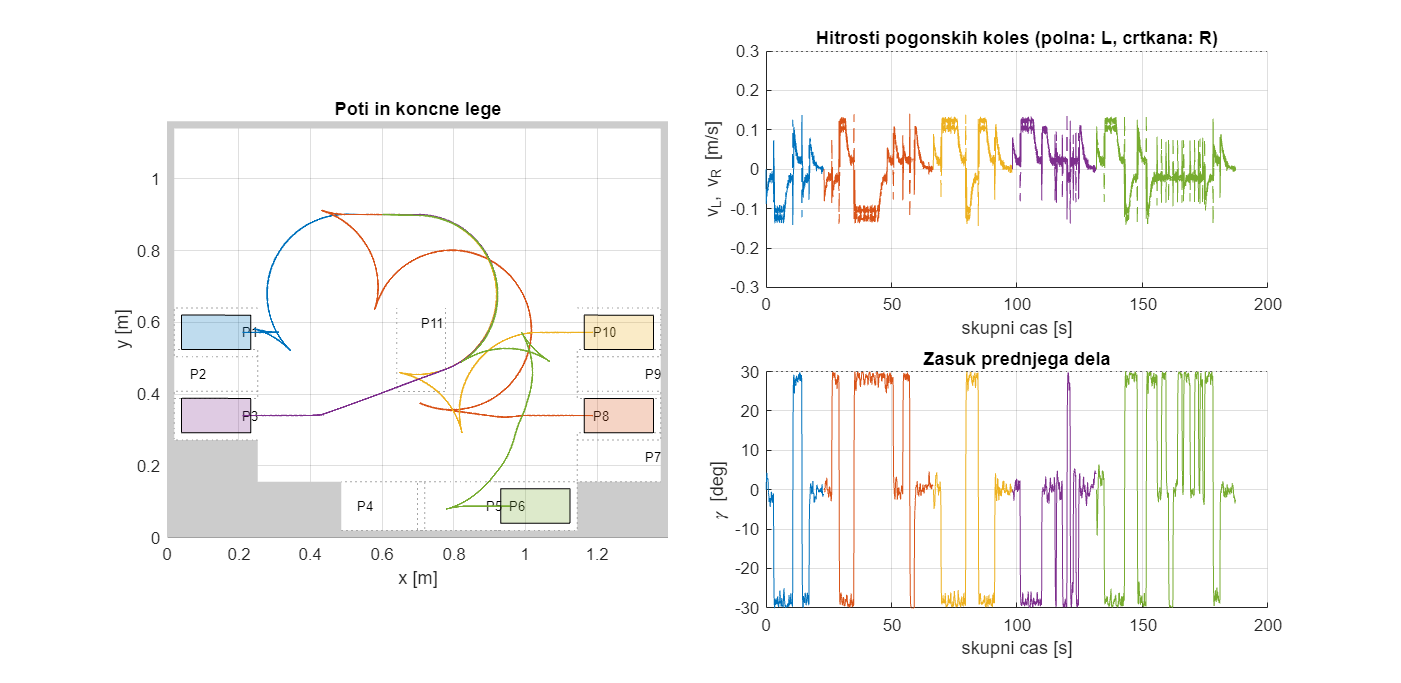

ans = 5x9 table
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    ________    ________    _________    ____

      1        1     23.13    0.90232    0.70589    0.036579    0.14146         1         0  
      2        8     43.53      2.075    0.50528    0.010655    0.14071         1         0  
      3       10     31.51     1.6492    0.53572    0.018516    0.14392         1         0  
      4        3     33.46     1.3448    0.69215    0.049103    0.14332         1         0  
      5        6     55.66     1.8076    0.48562    0.051287    0.14236         1         0  


store('ex3case1', data);
parkingResults(data, true)

### Case 2: From the same known initial configuration S to P2, P9, P7 and P4

rng(302);
data = runParkingCase(qS, [2, 9, 7, 4], true, noise);

P02: t=31.30 s, ed=0.454 mm, ephi=0.138 deg, trki=0
P09: t=34.29 s, ed=0.718 mm, ephi=0.099 deg, trki=0
P07: t=49.54 s, ed=0.484 mm, ephi=0.037 deg, trki=0
P04: t=56.53 s, ed=0.114 mm, ephi=0.432 deg, trki=0


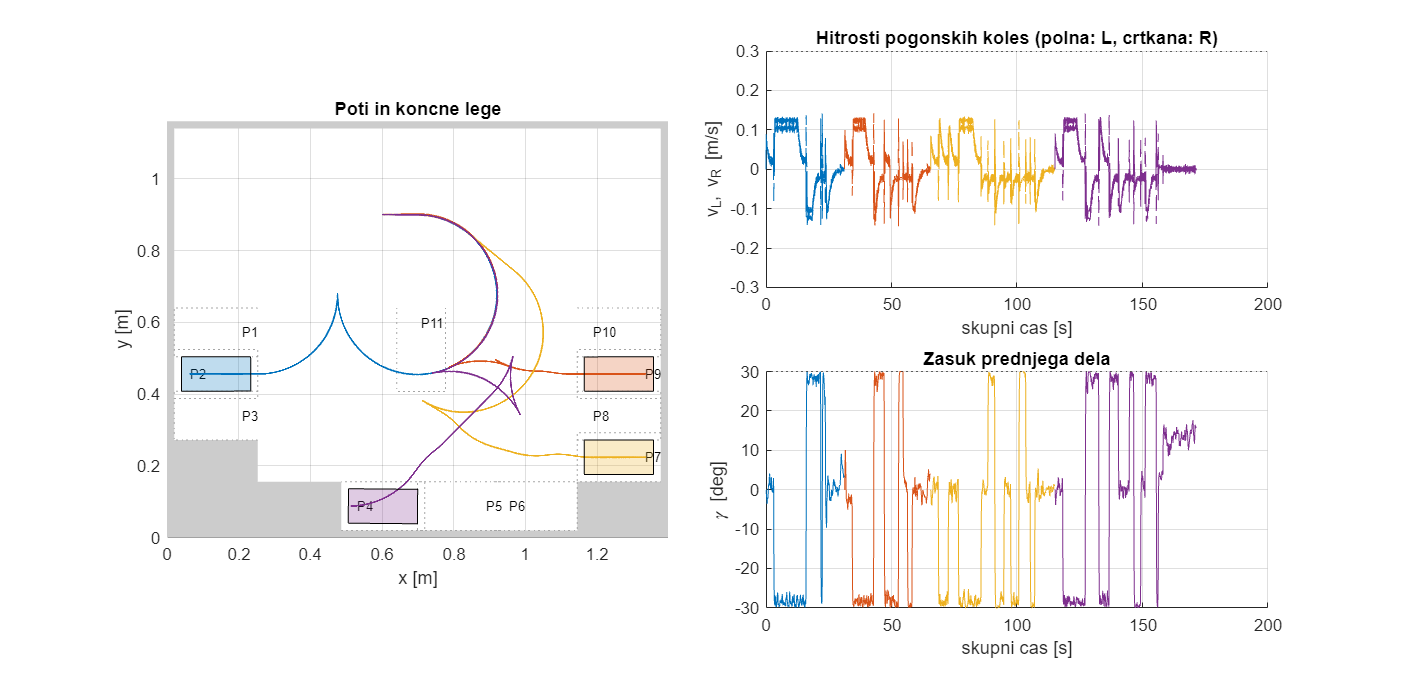

ans = 4x9 table
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1       2       31.3    1.6969    0.45393     0.13835    0.14489         1         0  
      2       9      34.29     1.348    0.71818    0.098514    0.14485         1         0  
      3       7      49.54    1.7486    0.48381    0.037366    0.14197         1         0  
      4       4      56.53    1.8623    0.11417     0.43233    0.14338         1         0  


store('ex3case2', data);
parkingResults(data, true)

### Case 3: From the same known initial configuration S to P1, P3, P10, P8, P6, P2, P7, P9, P4 and P5

rng(303);
data = runParkingCase(qS, [1, 3, 10, 8, 6, 2, 7, 9, 4, 5], true, noise);

P01: t=23.82 s, ed=0.527 mm, ephi=0.064 deg, trki=0
P03: t=33.18 s, ed=0.761 mm, ephi=0.041 deg, trki=0
P10: t=31.25 s, ed=0.677 mm, ephi=0.046 deg, trki=0
P08: t=42.89 s, ed=0.753 mm, ephi=0.032 deg, trki=0
P06: t=53.67 s, ed=0.562 mm, ephi=0.077 deg, trki=0
P02: t=31.26 s, ed=0.707 mm, ephi=0.122 deg, trki=0
P07: t=48.14 s, ed=0.542 mm, ephi=0.052 deg, trki=0
P09: t=34.92 s, ed=0.494 mm, ephi=0.159 deg, trki=0
P04: t=45.37 s, ed=0.696 mm, ephi=0.289 deg, trki=0
P05: t=58.32 s, ed=0.163 mm, ephi=0.447 deg, trki=0


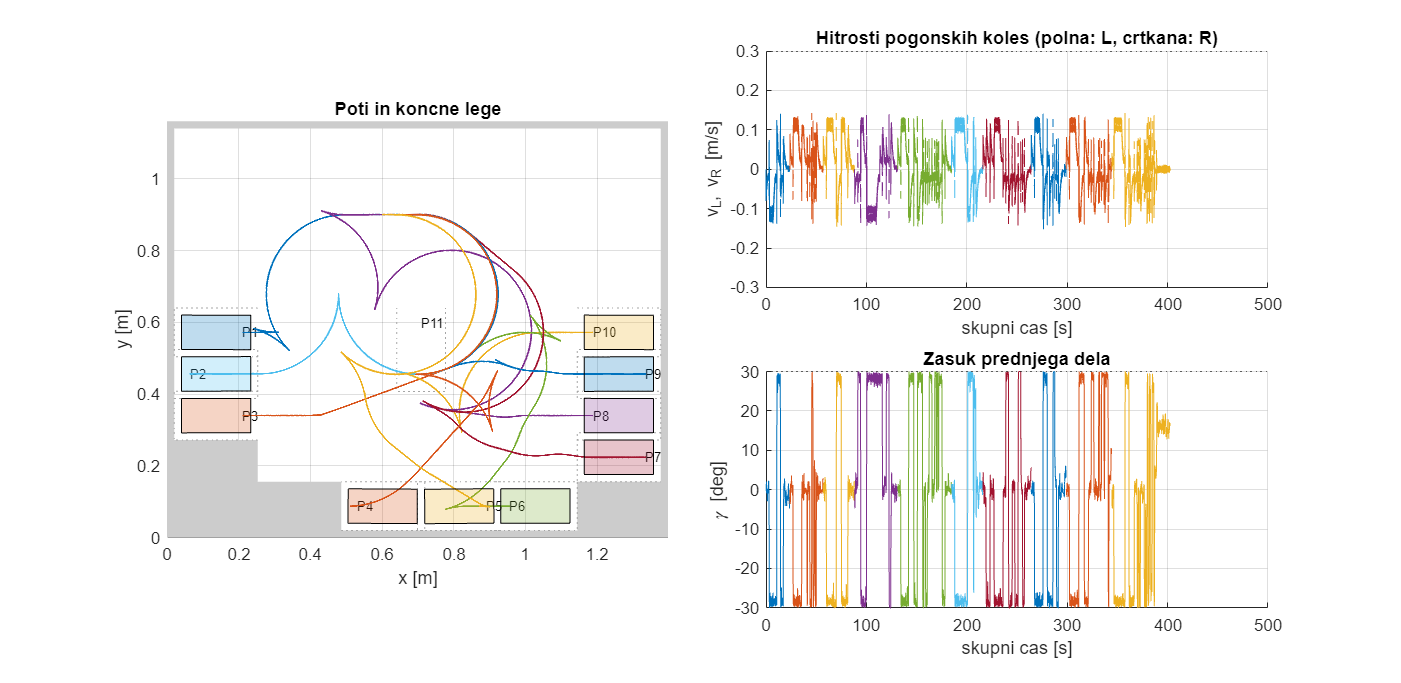

ans = 10x9 table
    robot    cilj    cas_s    pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    ______    _______    ________    ________    _________    ____

      1        1     23.82    0.9049     0.5272     0.06441    0.14116         1         0  
      2        3     33.18     1.344    0.76136    0.041382    0.14309         1         0  
      3       10     31.25    1.6523    0.67746    0.046145    0.15202         1         0  
      4        8     42.89    2.0755    0.75264    0.032091    0.14325         1         0  
      5        6     53.67    1.8472    0.56215    0.076955    0.14508         1         0  
      6        2     31.2

store('ex3case3', data);
parkingResults(data, true)

### Case 4: From the same known initial configuration S to P11, P1, P2, P9, P10, P5, P3, P8, P7, P4 and P6

rng(304);
data = runParkingCase(qS, [11, 1, 2, 9, 10, 5, 3, 8, 7, 4, 6], true, noise);

P11: t=16.61 s, ed=0.683 mm, ephi=0.108 deg, trki=0
P01: t=23.94 s, ed=0.440 mm, ephi=0.031 deg, trki=0
P02: t=34.49 s, ed=0.577 mm, ephi=0.013 deg, trki=0
P09: t=32.86 s, ed=0.592 mm, ephi=0.055 deg, trki=0
P10: t=41.45 s, ed=0.451 mm, ephi=0.069 deg, trki=0
P05: t=46.25 s, ed=0.705 mm, ephi=0.059 deg, trki=0
P03: t=39.72 s, ed=0.556 mm, ephi=0.107 deg, trki=0
P08: t=41.00 s, ed=0.567 mm, ephi=0.120 deg, trki=0
P07: t=50.15 s, ed=0.727 mm, ephi=0.086 deg, trki=0
P04: t=66.92 s, ed=0.710 mm, ephi=0.103 deg, trki=0
P06: t=64.51 s, ed=0.287 mm, ephi=0.420 deg, trki=0


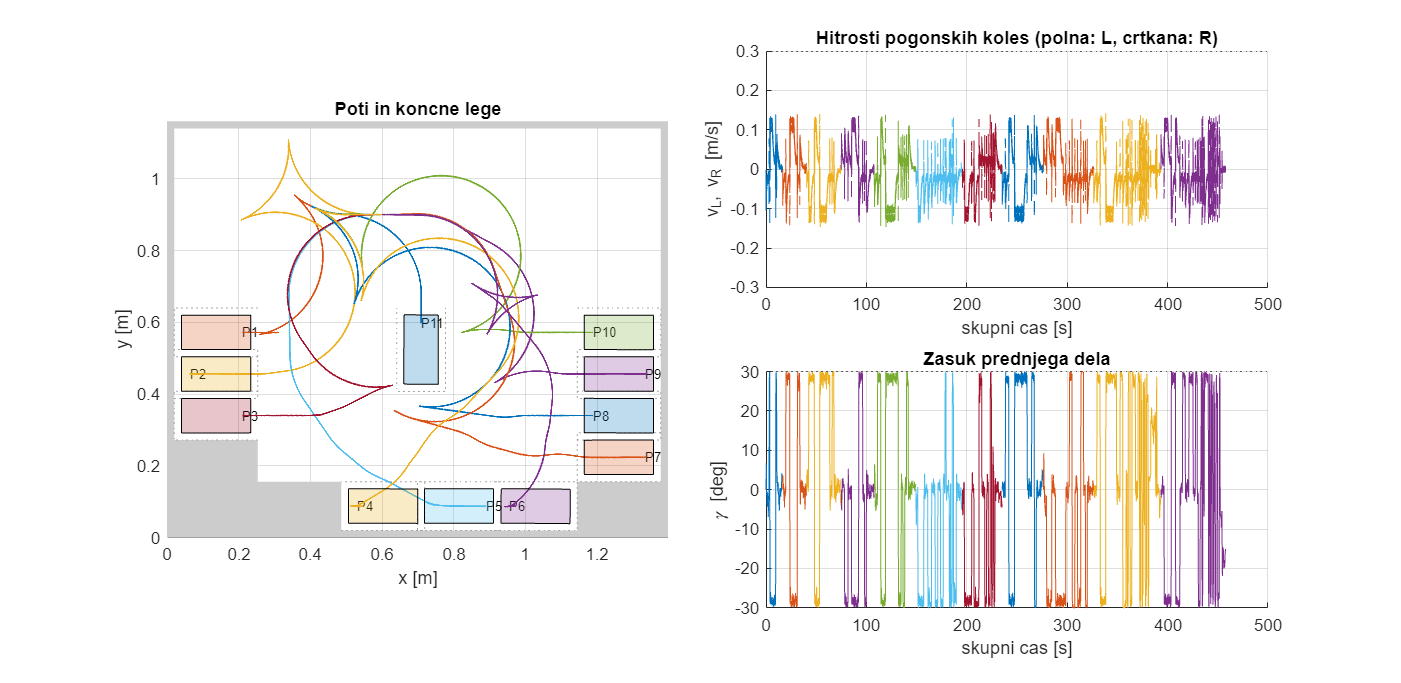

ans = 11x9 table
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg    vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    ________    ________    _________    ____

      1       11     16.61    0.55698    0.68343     0.10771    0.14377         1         0  
      2        1     23.94    0.90508    0.44019    0.031445    0.14206         1         0  
      3        2     34.49     1.6803     0.5767    0.012512    0.15028         1         0  
      4        9     32.86     1.2206    0.59167    0.055319    0.14196         1         0  
      5       10     41.45     1.8092    0.45083    0.069379    0.15187         1         0  
      6        5  

store('ex3case4', data);
parkingResults(data, true)

### Case 5: From random initial configurations to random parking spots

rng(601);
data = runParkingCase([], zeros(1,11), true, noise);

P06: t=66.05 s, ed=0.641 mm, ephi=0.132 deg, trki=0
P01: t=28.58 s, ed=0.369 mm, ephi=0.028 deg, trki=0
P05: t=40.77 s, ed=0.273 mm, ephi=0.075 deg, trki=0
P10: t=29.68 s, ed=0.634 mm, ephi=0.074 deg, trki=0
P08: t=33.80 s, ed=0.454 mm, ephi=0.031 deg, trki=0
P03: t=28.94 s, ed=0.574 mm, ephi=0.081 deg, trki=0
P11: t=40.93 s, ed=0.663 mm, ephi=0.032 deg, trki=0
P07: t=55.95 s, ed=0.628 mm, ephi=0.001 deg, trki=0
P09: t=70.82 s, ed=0.503 mm, ephi=0.102 deg, trki=0
P04: t=63.72 s, ed=0.623 mm, ephi=0.061 deg, trki=0
P02: t=51.94 s, ed=0.629 mm, ephi=0.054 deg, trki=0


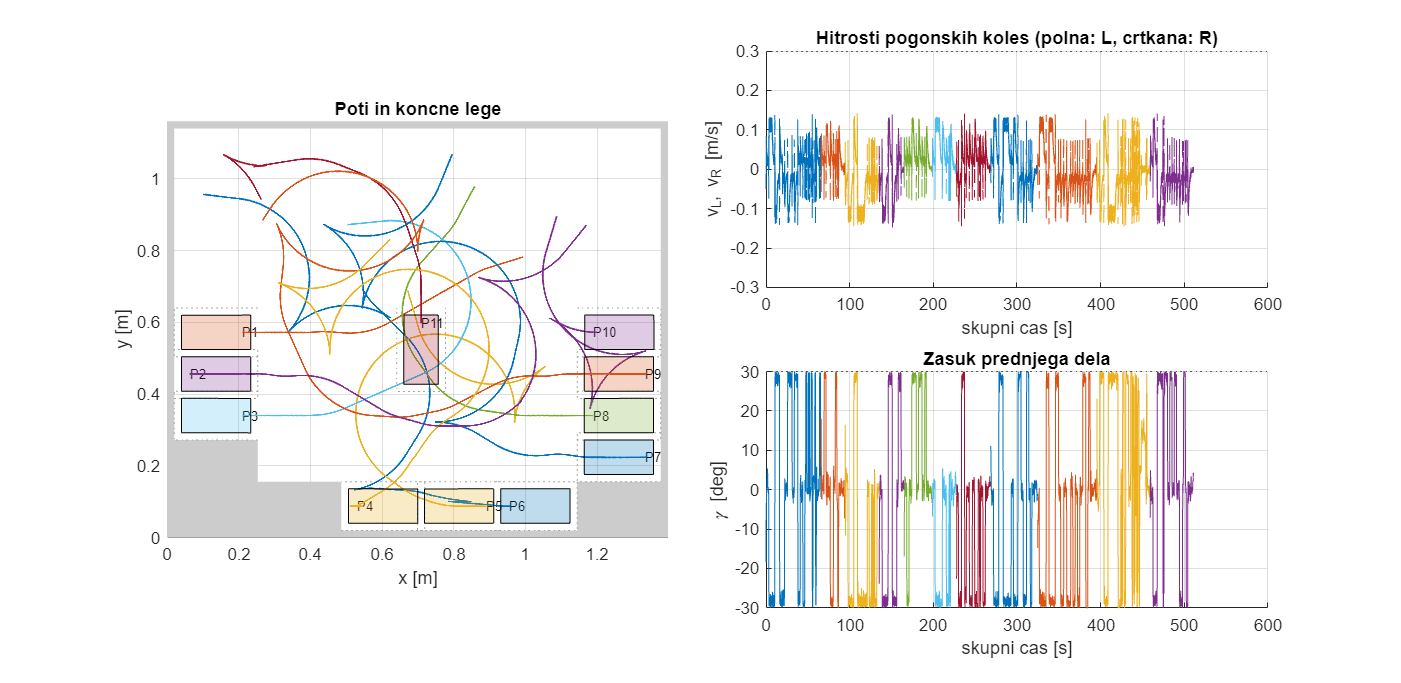

ans = 11x9 table
    robot    cilj    cas_s     pot_m      ed_mm     ephi_deg     vmax_m_s    amax_m_s2    trki
    _____    ____    _____    _______    _______    _________    ________    _________    ____

      1        6     66.05     2.2942    0.64095      0.13196    0.14278         1         0  
      2        1     28.58    0.83314    0.36871     0.027573    0.12336         1         0  
      3        5     40.77     1.9433    0.27268     0.075125     0.1447         1         0  
      4       10     29.68     1.2592    0.63424     0.073797    0.14807         1         0  
      5        8      33.8     1.1006    0.45389     0.030704    0.13107         1         0  
      6    

store('ex3random1', data);
parkingResults(data, true)

## Preverjanje z izvirnim simulatorjem

Datoteka originalSimulatorCheck.mat vsebuje neposredni preizkus simParking(qA,11,1,0), rng(101). Ujemanje s numericnim preizkusom je preverjeno za koncno lego, hitrosti koles in trke. Za ponovno izvedbo z animacijo uporabi zgornji klic v Command Window.

check = load('originalSimulatorCheck.mat');
numeric = load('ex1case1.mat');
assert(norm(check.data.qEnd-numeric.data.qEnd) < 1e-8);
assert(isequal(check.data.vl,numeric.data.vl));
assert(isequal(check.data.c,numeric.data.c));
disp('Numericni in izvirni simulator se ujemata.');

Numericni in izvirni simulator se ujemata.


## Opazanja in omejitve

Pri vec vozilih se poti spreminjajo glede na zasedenost. Omejitev zasuka zahteva vec premikov in menjav smeri, zlasti pri spodnjih parkirnih mestih. Ustavitev pred spremembo ukrivljenosti zmanjsa odstopanje od poti, vendar podaljsa cas. A* je zaradi krajsega racunanja utezen s faktorjem 3; optimalnost poti ni zagotovljena. Testi so koncni preizkusi z znanimi semeni, ne dokaz uspeha za vse mogoce realizacije suma.

## Datoteke za ponovitev

controlParking.m, controlParkingLim.m, parkingControl.m in parkingPlan.m sestavljajo resitev. runParkingCase.m, parkingResults.m in testParking.m so numericni preizkus, prikaz rezultatov in zbirka preverjanj. README.md opisuje zagon. MAT-datoteke ex1case*, ex2case*, ex3case* in ex*random1 vsebujejo rezultate tega porocila. Izvirni simulatorji ostanejo nespremenjeni; za vodenje niso potrebni dodatni MATLAB toolboxi.

## Prepare ZIP for submission

% Po izvedbi porocilo shrani (Ctrl+S), sele nato v Command Window:
% prepare
% Ponovitev vseh preverjanj: testParking(1)
% Animacija v izvirnem simulatorju:
% simParking(qA, 11, 1, 1)
% simParkingLim(qS, [1,8,10,3,6], 1, 1)

Verify that the ZIP file contains all required files and that homework.mlx is saved in the evaluated state (i.e. if it is reopened, all results and figures should be visible without running any code).